% Read EmoDB dataset
ads_emodb = audioDatastore(fullfile("EmoDB/wav/"));
% Define indices in filename where emotion and speaker codes are stored (end-?)
emotionIdx = 5;
speakerIdx = [10, 9];
% Define mapping for emotions IDs in file name
emotionMapping = {["W","L","E","A","F","T","N"], ...
                  ["Anger","Boredom","Disgust","Anxiety/Fear","Happy","Sad","Neutral"]};
% Build label table for all files
labelTable = buildLabelTable(ads_emodb, emotionIdx, speakerIdx, emotionMapping);
ads_emodb.Labels = labelTable;
% Subset files to only include anger, happy, and neutral
ads_emodb = subset(ads_emodb, find(ismember(cellstr(ads_emodb.Labels.Emotion), ["Sad", "Happy", "Anger"])));
% Subsample emotions so classes are balanced for training
ads_emodb = subsampleFiles(ads_emodb);
counts_emodb = summary(ads_emodb.Labels).Emotion.Counts;
counts_emodb = counts_emodb(counts_emodb > 0);

% Read ShEMO dataset (already downsampled in LSTM_ShEMO.mlx)
ads_shemo = audioDatastore(fullfile("downsampledDataShEMO/"));
% Define indices in filename where emotion and speaker codes are stored (end-?)
emotionIdx = 6;
speakerIdx = [9, 7];
% Define mapping for emotions IDs in file name
emotionMapping = {["A","F","H","N","S","W"], ...
                  ["Anger","Fear","Happy","Neutral","Sad","Surprised"]};
% Build label table for all files
labelTable = buildLabelTable(ads_shemo, emotionIdx, speakerIdx, emotionMapping);
ads_shemo.Labels = labelTable;
% Subset files to only include anger, happy, and neutral
ads_shemo = subset(ads_shemo, find(ismember(cellstr(ads_shemo.Labels.Emotion), ["Sad", "Happy", "Anger"])));
% Subsample emotions so classes are balanced for training
ads_shemo = subsampleFiles(ads_shemo, min(counts_emodb));

% Combine Audio Datastore objects from the two datasets
ads = audioDatastore(cat(1, ads_emodb.Files, ads_shemo.Files));
ads.Labels = cat(1, ads_emodb.Labels, ads_shemo.Labels);
% Summarize
summary(ads.Labels)

Variables:
    Speaker: 372×1 categorical
        Values:
            03       26   
            08       23   
            09       11   
            10       14   
            11       21   
            12       10   
            13       15   
            14       28   
            15       14   
            16       24   
            F0       11   
            F1       20   
            F2       10   
            F3       12   
            F4       16   
            F5        1   
            F6        4   
            F7       16   
            F8        8   
            F9        7   
            M0        4   
            M1        8   
            M2       10   
            M3       16   
            M4        9   
            M5       12   
            M6        7   
            M7        1   
            M8       11   
            M9        3   
    Emotion: 372×1 categorical
        Values:
            Anger             124   
            An

% Load the sampling frequency from file
netFolder = fullfile(pwd,"SpeechEmotionRecognition");
load(fullfile(netFolder,"network_Audio_SER.mat"));
fs = afe.SampleRate;

% Split dataset into train/test sets
[ads_train, ads_test] = splitTrainTest(ads, .8);

% Augment each audio file in the training set and return augmented
% sequences to use in the model
numAugmentations = 100;
[afe, sequencesTrain, labelsTrain, emptyEmotions] = processData("Combined_Train", ads_train, fs, numAugmentations);

Augmentation complete in 6.47 minutes.


% Augment each audio file in the test set and return augmented
% sequences to use in the model
[~, sequencesTest, labelsTest, ~] = processData("Combined_Test", ads_test, fs, numAugmentations);

Augmentation complete in 1.37 minutes.


% Specify the LSTM neural network configuration, including layer structure,
% dropout probabilities, and the number of LSTM units
dropoutProb1 = 0.3;
numUnits = 200;
dropoutProb2 = 0.6;
layers = [ ...
    sequenceInputLayer(afe.FeatureVectorLength)
    dropoutLayer(dropoutProb1)
    bilstmLayer(numUnits,OutputMode="last")
    dropoutLayer(dropoutProb2)
    fullyConnectedLayer(numel(categories(emptyEmotions)))
    softmaxLayer
    classificationLayer];

% Specify the training parameters, including mini batch size, initial
% learning rate, max epochs, etc.
miniBatchSize = 128;
initialLearnRate = 0.005;
learnRateDropPeriod = 2;
maxEpochs = 3;
options = trainingOptions("adam", ...
    MiniBatchSize=miniBatchSize, ...
    InitialLearnRate=initialLearnRate, ...
    LearnRateDropPeriod=learnRateDropPeriod, ...
    LearnRateSchedule="piecewise", ...
    MaxEpochs=maxEpochs, ...
    Shuffle="every-epoch", ...
    Verbose=false, ...
    Plots="Training-Progress");

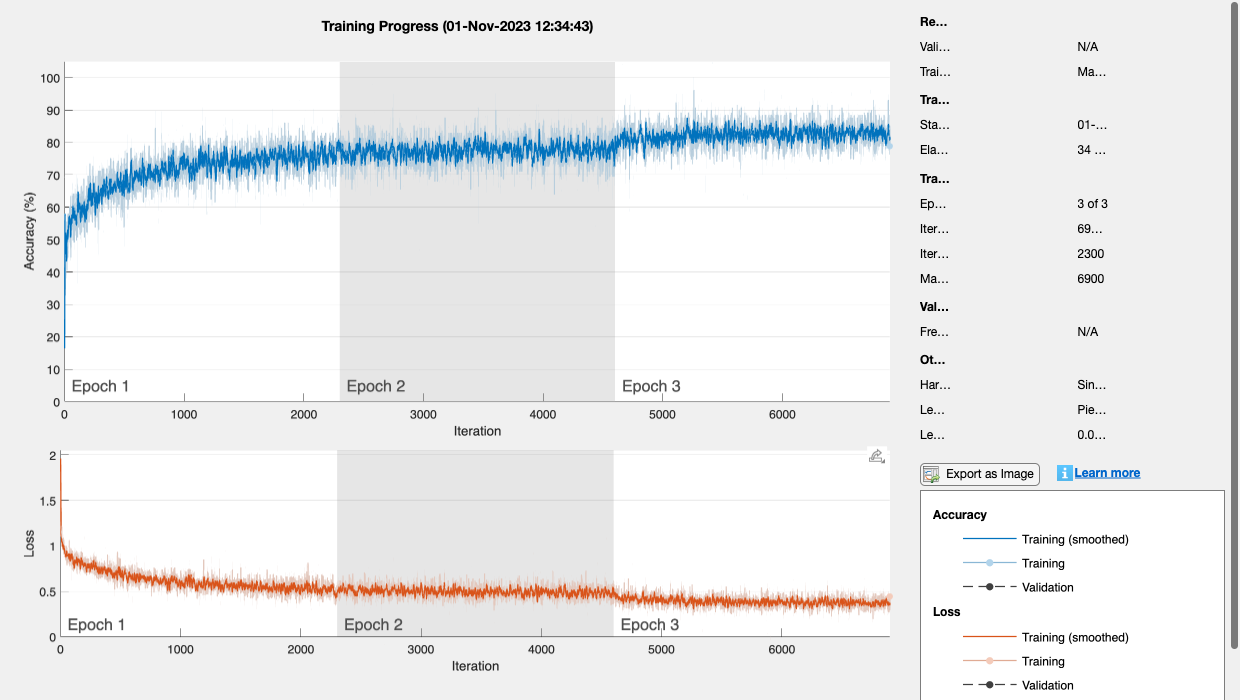

% Train the network using the specified parameters and training dataset
net = trainNetwork(sequencesTrain,labelsTrain,layers,options);

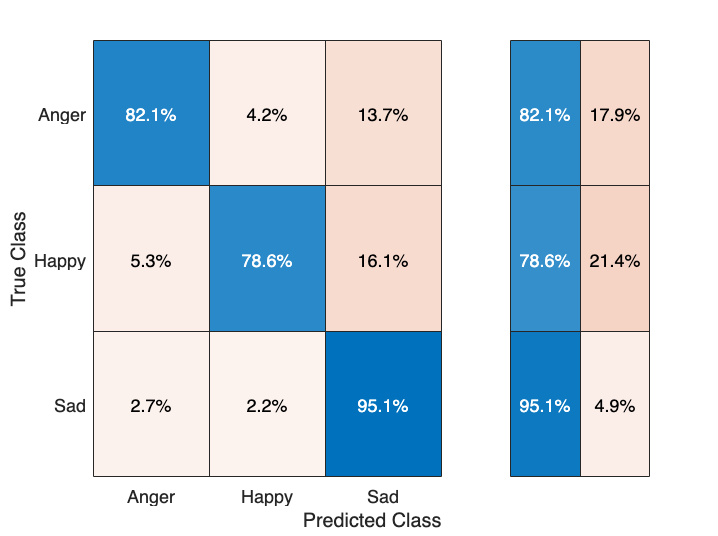

% Predict labels for the training set using the trained network
predictionsTrain = classify(net, sequencesTrain);
labelsTrain = removecats(labelsTrain);
predictionsTrain = removecats(predictionsTrain);
figure; confusionchart(labelsTrain, predictionsTrain, 'Normalization','row-normalized', 'RowSummary','row-normalized');

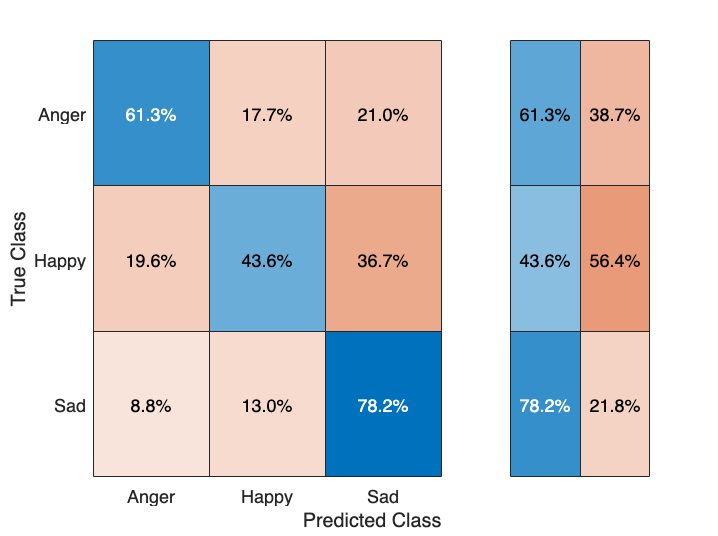

% Predict labels for the test set using the trained network
predictionsTest = classify(net, sequencesTest);
labelsTest = removecats(labelsTest);
predictionsTest = removecats(predictionsTest);
figure; confusionchart(labelsTest, predictionsTest, 'Normalization','row-normalized', 'RowSummary','row-normalized');

% Save all the data to use in LSTM_Cross_Predict.mlx
save("Workspace_Combined.mat", "-v7.3");